# BBC State Abstraction

clear;
close all;
bdclose('all');

## Load data

Load generated data from the MAT files

myFolder = "/Users/jiayangsong/Documents/git/AI-CPS-Ensemble/BBC/data_generation/generated_data/";
% myFolder = "/home/momentumlab/Documents/git/AI-CPS-Ensemble/BBC/data_generation/generated_data";

% check if folder path is valid
if ~isfolder(myFolder)
    errorMessage = sprintf('Error: The following folder does not exist:\n%s', myFolder);
    uiwait(warndlg(errorMessage));
    return;
end

% load all .MAT files under determined folder
filePattern = fullfile(myFolder, '*.mat');
matFiles = dir(filePattern);
[fileNumber, ~]= size(matFiles);
data = cell(fileNumber, 1);         % cell array to hold all simulation results

for k = 1:length(matFiles)
  baseFileName = matFiles(k).name;
  fullFileName = fullfile(myFolder, baseFileName);
  fprintf(1, 'Now reading %s\n', fullFileName);
  data{k} = load(fullFileName).results;
end

Now reading /Users/jiayangsong/Documents/git/AI-CPS-Ensemble/BBC/data_generation/generated_data/BBC_data_BBC-SAC-18-Jul-0.1-1-0.05.mat.mat
Now reading /Users/jiayangsong/Documents/git/AI-CPS-Ensemble/BBC/data_generation/generated_data/BBC_data_BBC-SAC-19-Jul-0.1-2-0.05.mat.mat
Now reading /Users/jiayangsong/Documents/git/AI-CPS-Ensemble/BBC/data_generation/generated_data/BBC_data_BBC-SAC-19-Jul-0.2-0.7-0.02.mat.mat
Now reading /Users/jiayangsong/Documents/git/AI-CPS-Ensemble/BBC/data_generation/generated_data/BBC_data_BBC-SAC-revised-2-21-Jul-0.2-1.5-0.1.mat.mat
Now reading /Users/jiayangsong/Documents/git/AI-CPS-Ensemble/BBC/data_generation/generated_data/BBC_data_BBC-SAC-revised-2-22-Jul-0.1-2-0.1.mat.mat
Now reading /Users/jiayangsong/Documents/git/AI-CPS-Ensemble/BBC/data_generation/generated_data/BBC_data_BBC-SAC-revised-2-23-Jul-0.2-2-0.1.mat.mat
Now reading /Users/jiayangsong/Documents/git/AI-CPS-Ensemble/BBC/data_generation/generated_data/BBC_data_BBC-SAC-revised-20-Jul-0.1-1-0

## Abstract MDP Construction

### Concrete MDP Concatenation

Combine collected data from each controller

% combine data from all simulations
mdpData = {};
for i = 1:length(data)-1
    mdpData = cat(2,mdpData, data{i}.data);
end

% extract concrete state, action, reward space
mdpSpace = cell2mat(mdpData');      % concrete MDP
numSample = length(mdpSpace);
abMdpSpace = zeros(numSample, 6);   % abstract MDP

stateSpace = mdpSpace(:, 1:7);      % concrete state
actionSpace = mdpSpace(:,8:9);      % concrete action
rewardSpace = mdpSpace(:,10:12);    % concrete reward

% number of unique concrete states and actions
numConcreteState = length(unique(stateSpace,'rows'));
numConcreteAction = length(unique(actionSpace,'rows'));

% number of unique concrete transitions
concreteTranSpace = cat(2, mdpSpace(1:end-1,1:7), mdpSpace(2:end,1:7));
numConcreteTran = length(unique(concreteTranSpace,'rows'));

fprintf("Number of samples: %i" + ...
    "\nNumber of concrete states: %i" + ...
    "\nNumber of concrete actions: %i"+ ...
    "\nNumber of concrete transitions: %i",...
    length(mdpSpace), numConcreteState, numConcreteAction, numConcreteTran);

Number of samples: 1655500
Number of concrete states: 1655500
Number of concrete actions: 1581955
Number of concrete transitions: 1655499

### Action aggregation

**Unifromaly** partiion the action space

Collected data: lateral deviation, relative yaw angle, steering angle, lateral deviation reward, yaw angle reward

The partition interval is:  actionInverval = actionRange * 10% = 0.1

% abstract action space 
actionInterval = cell(1,2);
abActionSpace = actionSpace;

for i = 1:2
    action = actionSpace(:,i);  % actionSpace on 1 action 
    abAction = action;
    actionMin = min(action);
    actoinMax = max(action);
    Interval = (actoinMax - actionMin)*0.1;
    
    actionTreshold = [[-inf,actionMin:Interval:actoinMax];[actionMin:Interval:actoinMax, +inf]]';
    actionTreshold = mat2cell(actionTreshold, ones(1,length(actionTreshold)),2);
    actionInterval{i} = actionTreshold;

    for j = 1:length(actionTreshold)
        temp = num2cell(actionTreshold{j});
        [lower, upper] = temp{:};
        abAction((action>lower) & (action <= upper)) = j;
    end
    abActionSpace(:,i) = abAction;
end

% unique action pairs
[C,~,ic] = unique(abActionSpace, 'rows');
abActionSpace(:,3) = ic;
numActionPair = length(C)^2;
actionToIndexTable = cat(2,C,(1:length(C))'); 

% substitute concrete action space with abstract action space
abMdpSpace(:, 4:6) = abActionSpace;
numAbAction = length(actionTreshold)^2;
numAbActionInData = length(unique(abActionSpace,'rows'));

fprintf("Split action space with interval: %.2f" + ...
    " \nNumber of possible abstracted actions: %i" + ...
    "\nNumber of abstracted actions in data: %i", Interval, numActionPair, numAbActionInData);

Split action space with interval: 0.05 
Number of possible abstracted actions: 10816
Number of abstracted actions in data: 104

### Reward Clustering

Cluster concrete states into abstract clusters based on rewards

Split reward space into multiple intervals. Each interval shoud contain a minimum number of concrete states. 

Three clusteriing creteria: **Minimum Distance**,** Maximum Distance, Minimum Points**

- minDistance = Reward range * A%

- maxDistance = Reward range * B%

- minPoints = Number of concrete state *C%

% minimum distance and minimum number for a cluster
dimReward = size(rewardSpace);       % dimension of the semantics reward
dimReward = dimReward(2)-1;             
rewardIndex = zeros(numSample, dimReward);
rewardInterval = cell(1,dimReward);

% percentage parameter to compute minimum distance and minimum number of states
RewardMinDistPerc = [0.001,0.001];
RewardMinNumPerc = [0.001, 0.001];
RewardMaxDistThres = [0.02, 0.02];

% abstraction on each reward dimension
for i = 1:dimReward
    reward = rewardSpace(:,i);
    RewardMinDist = (max(reward) - min(reward))*RewardMinDistPerc(i);
    RewardMinNum = round(numSample*RewardMinNumPerc(i));
    rewardMaxDist = RewardMaxDistThres(i)*(max(reward) - min(reward));
    
    [index, interval] = RewardClustering(reward, RewardMinDist, RewardMinNum,rewardMaxDist);
    rewardIndex(:,i) = index;
    rewardInterval{i} = interval;
end

% unique abstract reward index pair (only for rewardDimension >=2)
[C,~,ic] = unique(rewardIndex, 'rows');

% look-up table to find index of abstract reward
rewardToIndexTable = cat(2,C,(1:length(C))'); 
rewardIndex(:, end+1) = ic;
abMdpSpace(:,1:3) = rewardIndex;
fprintf("Number of abstract state after reward clustering: %i", length(unique(abMdpSpace(:,3))));

Number of abstract state after reward clustering: 362

**Compute average reward of each semantics for each abstract state**

abstract reward space = [ballReward, plateReward, fnalReward]

**abAvgReward**: [abStateNum, 3]

**abRewardSpace**: [numSamples, 3]

abStateNum = length(unique(abMdpSpace(:,3)));
abAvgReward = ones(abStateNum,3);
abRewardSpace = zeros(numSample,3);

for i = 1:abStateNum
    abAvgReward(i,1) = mean(rewardSpace(rewardIndex(:,3)==i,1));
    abAvgReward(i,2) = mean(rewardSpace(rewardIndex(:,3)==i,2));
    abAvgReward(i,3) = mean(rewardSpace(rewardIndex(:,3)==i,3));
    
    abRewardSpace(rewardIndex(:,3)==i, 1) = abAvgReward(i,1) ;
    abRewardSpace(rewardIndex(:,3)==i, 2) = abAvgReward(i,2) ;
    abRewardSpace(rewardIndex(:,3)==i, 3) = abAvgReward(i,3) ;
end

## Abstraction Error 

Abstract  state reward error on each semantics

**abRewardError** = [meanError, maxError, Std]

abRewardError = zeros(3,3);

for i =1:3
    rewardError = abs((rewardSpace(:,i) - abRewardSpace(:,i)));
    abRewardError(i,1) = mean(rewardError);
    abRewardError(i,2) = max(rewardError);
    abRewardError(i,3) = std(rewardError);
end

fprintf("Ball-Reward-Error, Mean: %f Max: %f,  std: %f", abRewardError(1,1),abRewardError(1,2),abRewardError(1,3));

Ball-Reward-Error, Mean: 0.003778 Max: 0.019862,  std: 0.003226

fprintf("Plate-Reward-Error, Mean: %f Max: %f,  std: %f", abRewardError(2,1),abRewardError(2,2),abRewardError(2,3));

Plate-Reward-Error, Mean: 0.000502 Max: 0.014201,  std: 0.001581

fprintf("Final-Reward-Error, Mean: %f Max: %f,  std: %f", abRewardError(3,1),abRewardError(3,2),abRewardError(3,3));

Final-Reward-Error, Mean: 0.017969 Max: 0.094117,  std: 0.015656

#### Plot PDF of rewards in terms of different semantics

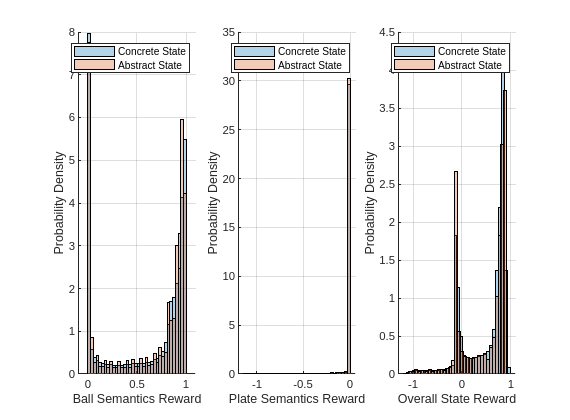

nbins = int8(abStateNum/10);

figure;
subplot(1,3,1);
hold on 
h1 = histogram(rewardSpace(:,1), nbins,'FaceAlpha',0.3, 'Normalization','pdf');
h2 = histogram(abRewardSpace(:,1), nbins,'FaceAlpha',0.3,'Normalization','pdf');
hold off
grid on;
xlim([-1, 1]);
legend("Concrete State", "Abstract State");
xlabel('Ball Semantics Reward') ;
ylabel('Probability Density') ;
xlim([-0.1, 1.1]);

% figure;
subplot(1,3,2);
hold on 
h1 = histogram(rewardSpace(:,2),nbins, 'FaceAlpha',0.3, 'Normalization','pdf');
h2 = histogram(abRewardSpace(:,2),nbins, 'FaceAlpha',0.3,'Normalization','pdf');
hold off
grid on;
% xlim([-0.1, 0.6]);
legend("Concrete State", "Abstract State");
xlabel('Plate Semantics Reward') ;
ylabel('Probability Density') ;

subplot(1,3,3);
hold on 
h1 = histogram(rewardSpace(:,3),nbins, 'FaceAlpha',0.3, 'Normalization','pdf');
h2 = histogram(abRewardSpace(:,3),nbins, 'FaceAlpha',0.3,'Normalization','pdf');
hold off
grid on;
% xlim([-1, 1]);
legend("Concrete State", "Abstract State");
xlabel('Overall State Reward') ;
ylabel('Probability Density') ;pos = get(gcf, 'Position');
set(gcf, 'Position',pos+[0 -100 10 0.1])

#### Two-sample Kolmogorov-Smirnov test

**Hypothesis test result: **h = 0 if two data sets are from the same continuous distribution, and 0 otherwise

p-value:

[h,p,ks2stat] = kstest2(h1.Values,h2.Values,'Alpha',0.02);
disp([h,p,ks2stat]);

         0    0.9713    0.1111



#### Plot CDF of rewards in terms of different semantics

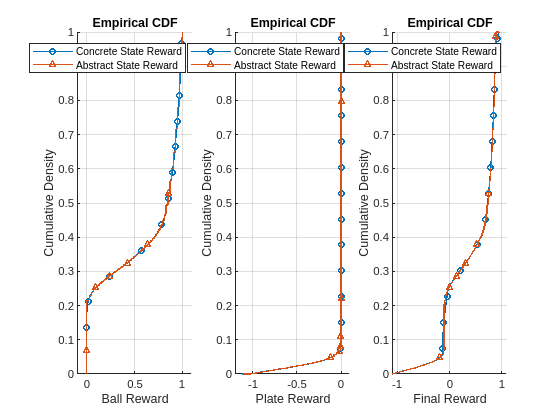

figure;
h1Indice = 250000;
h2Indice = 100;
subplot(1,3,1);
hold on 
h1 = cdfplot(rewardSpace(:,1));
h2 = cdfplot(abRewardSpace(:,1));
h1.LineWidth = 1;
h2.LineWidth = 1;
h1.Marker = "o";
h2.Marker = "^";
h1.MarkerIndices = 1:h1Indice:length(h1.YData);
h2.MarkerIndices = 1:h2Indice:length(h2.YData);
h1.MarkerSize = 4;
h2.MarkerSize = 4;
hold off
grid on;
xlim([-0.1, 1.1]);
legend("Concrete State Reward", "Abstract State Reward");
xlabel('Ball Reward') ;
ylabel('Cumulative Density') ;

subplot(1,3,2);
hold on 
h1 = cdfplot(rewardSpace(:,2));
h2 = cdfplot(abRewardSpace(:,2));
h1.LineWidth = 1;
h2.LineWidth = 1;
h1.Marker = "o";
h2.Marker = "^";
h1.MarkerIndices = 1:h1Indice:length(h1.YData);
h2.MarkerIndices = 1:h2Indice:length(h2.YData);
h1.MarkerSize = 4;
h2.MarkerSize = 4;
hold off
grid on;
xlim([-1.2, 0.1]);
legend("Concrete State Reward", "Abstract State Reward");
xlabel('Plate Reward') ;
ylabel('Cumulative Density') ;

subplot(1,3,3);
hold on 
h1 = cdfplot(rewardSpace(:,3));
h2 = cdfplot(abRewardSpace(:,3));
h1.LineWidth = 1;
h2.LineWidth = 1;
h1.Marker = "o";
h2.Marker = "^";
h1.MarkerIndices = 1:h1Indice:length(h1.YData);
h2.MarkerIndices = 1:h2Indice:length(h2.YData);
h1.MarkerSize = 4;
h2.MarkerSize = 4;
hold off
grid on;
xlim([-1.1, 1.1]);
legend("Concrete State Reward", "Abstract State Reward");
xlabel('Final Reward') ;
ylabel('Cumulative Density') ;

## Abstract Transition Construction

Partition existing abstract state further w.r.t. transitions

if two abstract state have identical distribution under same action, they can be considered as one abstract state, vice versa.

**abTran** = [abState, abAction, nextAbState, latReward, yawReward, totalReward, tranIndex]

**tranTable** = [abState, abAction, latReward, yawReward, totalReward]

abTranReward = [latReward, yawReward, totalReward, tranIndex, abLatReward, abYawReward, abTotalReward, tranIndex,]

% abstract transition space
abStateIndex = abMdpSpace(:,3);                                        % abstract state index
abTran = cat(2, abMdpSpace(:,[3,6]), [abMdpSpace(2:end,3);0]);        % next abstract state & abstract action
abTran = cat(2, abTran, abRewardSpace);                                % reward of the next state

% unique state-action pair
[C,ia,ic] = unique(abTran(:,1:2), 'rows');
abTran = cat(2, abTran, ic);
numStateActionPair = length(C);

% remove the last state with no transition
samplePerSim = 300;   % num of samples per simulation
abTran = abTran(~rem(1:numSample,samplePerSim)==0,:);

% state-action -> next state
tranTable = cat(2,C,zeros(numStateActionPair,3));
abTranReward = cat(2, rewardSpace(~rem(1:numSample,samplePerSim)==0,:), zeros(length(abTran), 4));
% abTranReward = cat(2, rewardSpace, zeros(length(abTran), 4));

abTranReward(:,4) = abTran(:,7);

% compute average of the next possible states
for i = 1: numStateActionPair
    tranTable(i,3) = mean(abTran(abTran(:,7)==i, 4));       % avg next ball reward
    tranTable(i,4) = mean(abTran(abTran(:,7)==i, 5));       % avg next plate reward
    tranTable(i,5) = mean(abTran(abTran(:,7)==i, 6));       % avg next total reward
end

fprintf("Number of abstract transition: %i", max(abTran(:,7)));

Number of abstract transition: 13336

**Transition Reward Error**

abTranRewardError = [meanError, maxError, Std]

for i = 1: numStateActionPair
    abTranReward(abTranReward(:,4)==i,5) = mean(abTranReward(abTranReward(:,4)==i,1));
    abTranReward(abTranReward(:,4)==i,6) = mean(abTranReward(abTranReward(:,4)==i,2));
    abTranReward(abTranReward(:,4)==i,7) = mean(abTranReward(abTranReward(:,4)==i,3));
end

abTranRewardError = zeros(3,3);

for i =1:3
    rewardError = abs((abTranReward(:,i) - abTranReward(:,i+4)));
    abTranRewardError(i,1) = mean(rewardError);
    abTranRewardError(i,2) = max(rewardError);
    abTranRewardError(i,3) = std(rewardError);
end

fprintf("Ball-Tran-Reward-Error, Mean: %f Max: %f,  std: %f", abTranRewardError(1,1),abTranRewardError(1,2),abTranRewardError(1,3));

Steady-Tran-Reward-Error, Mean: 0.003744 Max: 0.019693,  std: 0.003223

fprintf("Plate-Tran-Reward-Error, Mean: %f Max: %f,  std: %f", abTranRewardError(2,1),abTranRewardError(2,2),abTranRewardError(2,3));

Edge-Tran-Reward-Error, Mean: 0.000489 Max: 0.016204,  std: 0.001555

fprintf("Final-Tran-Reward-Error, Mean: %f Max: %f,  std: %f", abTranRewardError(3,1),abTranRewardError(3,2),abTranRewardError(3,3));

Final-Tran-Reward-Error, Mean: 0.015799 Max: 0.104441,  std: 0.014560

#### Plot PDF of transition rewards in terms of different semantics

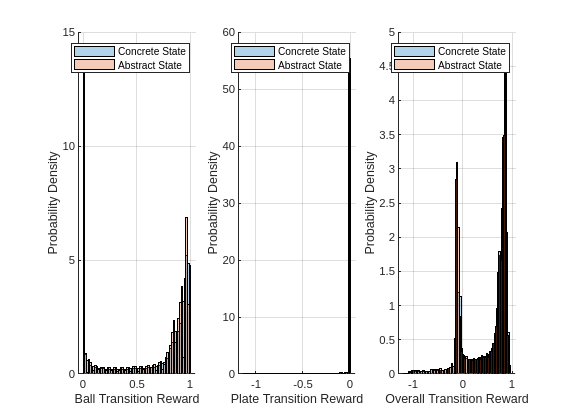

nbins = int8(numStateActionPair/200);

figure;
subplot(1,3,1);
hold on 
h1 = histogram(abTranReward(:,1), nbins,'FaceAlpha',0.3, 'Normalization','pdf');
h2 = histogram(abTranReward(:,5), nbins,'FaceAlpha',0.3,'Normalization','pdf');
hold off
grid on;
% xlim([-1, 1]);
legend("Concrete State", "Abstract State");
xlabel('Ball Transition Reward') ;
ylabel('Probability Density') ;

subplot(1,3,2);
hold on 
h1 = histogram(abTranReward(:,2),nbins, 'FaceAlpha',0.3, 'Normalization','pdf');
h2 = histogram(abTranReward(:,6),nbins, 'FaceAlpha',0.3,'Normalization','pdf');
hold off
grid on;
% xlim([-1, 1]);
legend("Concrete State", "Abstract State");
xlabel('Plate Transition Reward') ;
ylabel('Probability Density') ;

subplot(1,3,3);
hold on 
h1 = histogram(abTranReward(:,3),nbins, 'FaceAlpha',0.3, 'Normalization','pdf');
h2 = histogram(abTranReward(:,7),nbins, 'FaceAlpha',0.3,'Normalization','pdf');
hold off
grid on;
% xlim([-1, 1]);
legend("Concrete State", "Abstract State");
xlabel('Overall Transition Reward') ;
ylabel('Probability Density') ;pos = get(gcf, 'Position');
set(gcf, 'Position',pos+[0 -100 10 0.1])

Up to now, we have the look up table for abstract state and abstract transition

**The reward of an abstract state =  average reward of all concrete state inside **

**The reward of a abstract transition = average reward of all possible next abstract state**

## Convert a concrete state to abstract state

GIven a concrete state we can convert it to an abstract state with reward.

With an abstract action, we can estimate the transition to next possible states.

testInput= mdpData{1,1};
testInput = testInput(1,:);
testReward = rewardSpace(1,:);
testAction = testInput(8:9);

% upper bound of all action intervals
actionUB_1 = cell2mat(actionInterval{1});
actionUB_1 = actionUB_1(:,2);
actionUB_2 = cell2mat(actionInterval{2});
actionUB_2 = actionUB_2(:,2);

abAction_1 = find(actionUB_1 >= testAction(1), 1, 'first');
abAction_2 = find(actionUB_2 >= testAction(2), 1, 'first');

abACtion = actionToIndexTable(actionToIndexTable(:,1)==abAction_1 & actionToIndexTable(:,2)==abAction_2,3);

rewardUB_1 = cell2mat(rewardInterval{1}');
rewardUB_1 = rewardUB_1(:,2);
rewardUB_2 = cell2mat(rewardInterval{2}');
rewardUB_2 = rewardUB_2(:,2); 

abReward_1 = find(rewardUB_1 >= testReward(1), 1, 'first');
abReward_2 = find(rewardUB_2 >= testReward(2), 1, 'first');

abState = rewardToIndexTable(rewardToIndexTable(:,1)==abReward_1 & rewardToIndexTable(:,2)==abReward_2,3);
tranReward = tranTable(tranTable(:,1)==abState & tranTable(:,2)==abACtion,2);

% if the abstract state-action pair does not exist
if isempty(tranReward)
    tranReward = 0;
end

## Combine data & Establish abstract model

Combine results from abstract states and abstract transition to build up the complete abstract model

% save abstract states and transitions
controllerName = strings(fileNumber,1);
for i = 1:fileNumber
    tempName = matFiles(i).name;
    controllerName(i) = tempName(1:end-4);
end

name = "BBC_abstract_model";

abModel= struct('name', name,...
                'controllerName', controllerName,...
                'actionUB_1', actionUB_2,...
                'actionUB_2', actionUB_2,...
                'actionToIndexTable', actionToIndexTable,...
                'rewardUB_1', rewardUB_1,...
                'rewardUB_2', rewardUB_2,...
                'rewardToIndexTable', rewardToIndexTable,...
                'tranTable', tranTable);

**Collect abstract state and tranitiosns for later controller selection**

% abstract state and transition from identical input for comparison
identicalNum = 12;
identicalSimNum = 500;
[compareState, compareTran] = deal(cell(identicalNum,1));
compareStateData = abStateIndex;
compareTranData = abTran(:,7);

% for i = 1:identicalNum
%     compareState{i} = compareStateData(identicalSimNum*samplePerSim*(i-1)+1:identicalSimNum*samplePerSim*i);
%     compareTran{i} = compareTranData((identicalSimNum*(samplePerSim-1))*(i-1)+1:(identicalSimNum*(samplePerSim-1))*i);
% end
% 
% compareName = controllerName(fileNumber-identicalNum+1:end);
% abCompare= struct('name', {compareName},...
%                 'state', {compareState},...
%                 'transition', {compareTran});

#### Data saving

Save abstract model resutls (data) into MAT file.

The MAT file contains a cell array with structure arrays as elements, each structure array contains an abstract model with following fields:

- raw_data: original simulation results, no data processing applied

- abs_state: abstract state

- abs_tran: abstract transition

% save results in a MAT file
is_save = true;

if is_save
    save(name+".mat", "abModel");
    disp(name + " saved");

%     save("AFC_comparison.mat", "abCompare");
%     disp("AFC_comparison saved");
end

BBC_abstract_model saved
